### 探索数据的基本特征

载入数据，使用相同的变量名称方便后续转移代码

Q1.1 Perform a statistical analysis of the portfolio returns, describing your main findings.

Use the same variable names to help code copying and pasting

datatable= readtable("Stocks_merge.csv")

datatable = 2768×7 table
      Ticker       AAPL      AMZN     GOOGL      IBM       MSFT      NVDA  
    __________    ______    ______    ______    ______    ______    _______

           NaT       NaN       NaN       NaN       NaN       NaN        NaN
    2014-01-02    17.215    19.899    27.755    111.76    30.996    0.37397
    2014-01-03    16.837    19.822    27.553    112.43    30.788    0.36949
    2014-01-06    16.929    19.681     27.86    112.04    30.137    0.37444
    2014-01-07    16.808    19.902    28.397    114.28    30.371    0.38057
    2014-01-08    16.914    20.096    28.456    113.23    29.829    0.38576
    2014-01-09    16.698    20.051    28.182    112.87    29.637    0.37137
    2014-01-10    16.587    19.883    28.181     112.8    30.062     0.3709
    2014-01-13    16.674    19.549    28.001    110.93    29.178    0.36218
    2014-01-14    17.006    19.877     28.66    111.99    29.845    0.37349
    2014-01-15    17.347    19.794     28.64    113.09    30.6

data = table2array(datatable(2:end,2:end))

data =    17.2154   19.8985   27.7552  111.7598   30.9964    0.3740
   16.8372   19.8220   27.5528  112.4284   30.7879    0.3695
   16.9290   19.6815   27.8600  112.0429   30.1373    0.3744
   16.8080   19.9015   28.3971  114.2777   30.3708    0.3806
   16.9144   20.0960   28.4562  113.2295   29.8286    0.3858
   16.6984   20.0505   28.1821  112.8741   29.6368    0.3714
   16.5870   19.8830   28.1806  112.8019   30.0622    0.3709
   16.6738   19.5490   28.0011  110.9345   29.1780    0.3622
   17.0056   19.8770   28.6599  111.9947   29.8453    0.3735
   17.3470   19.7935   28.6404  113.0910   30.6628    0.3775


date = table2array(datatable(3:end,1))

date = 2766×1 datetime 数组
   2014-01-03
   2014-01-06
   2014-01-07
   2014-01-08
   2014-01-09
   2014-01-10
   2014-01-13
   2014-01-14
   2014-01-15
   2014-01-16
   2014-01-17
   2014-01-21
   2014-01-22
   2014-01-23
   2014-01-24
   2014-01-27
   2014-01-28
   2014-01-29
   2014-01-30
   2014-01-31
   2014-02-03
   2014-02-04
   2014-02-05
   2014-02-06
   2014-02-07
   2014-02-10
   2014-02-11
   2014-02-12
   2014-02-13
   2014-02-14


[nrows,ncols] = size(data)

nrows = 2767

ncols = 6

%simple return
sim_returns = (data(2:end,:)-data(1:end-1,:))./data(1:end-1,:)

sim_returns =    -0.0220   -0.0038   -0.0073    0.0060   -0.0067   -0.0120
    0.0055   -0.0071    0.0111   -0.0034   -0.0211    0.0134
   -0.0072    0.0112    0.0193    0.0199    0.0077    0.0164
    0.0063    0.0098    0.0021   -0.0092   -0.0179    0.0136
   -0.0128   -0.0023   -0.0096   -0.0031   -0.0064   -0.0373
   -0.0067   -0.0084   -0.0001   -0.0006    0.0144   -0.0013
    0.0052   -0.0168   -0.0064   -0.0166   -0.0294   -0.0235
    0.0199    0.0168    0.0235    0.0096    0.0229    0.0313
    0.0201   -0.0042   -0.0007    0.0098    0.0274    0.0107
   -0.0056   -0.0002    0.0066    0.0054    0.0035    0.0031


% log returns
log_returns = log(data(2:end,:)./data(1:end-1,:))

log_returns =    -0.0222   -0.0039   -0.0073    0.0060   -0.0068   -0.0121
    0.0054   -0.0071    0.0111   -0.0034   -0.0214    0.0133
   -0.0072    0.0111    0.0191    0.0198    0.0077    0.0162
    0.0063    0.0097    0.0021   -0.0092   -0.0180    0.0135
   -0.0129   -0.0023   -0.0097   -0.0031   -0.0065   -0.0380
   -0.0067   -0.0084   -0.0001   -0.0006    0.0143   -0.0013
    0.0052   -0.0169   -0.0064   -0.0167   -0.0299   -0.0238
    0.0197    0.0166    0.0233    0.0095    0.0226    0.0308
    0.0199   -0.0042   -0.0007    0.0097    0.0270    0.0107
   -0.0056   -0.0002    0.0066    0.0054    0.0035    0.0031


% build an equal weight portfolio
eqa_w = ones(1,ncols)/ncols

eqa_w =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667



% Calculate the portfolio return for each day (weighted average)
% mean as because weights are equal
port_returns = mean(log_returns,2)% daily log return

port_returns =    -0.0077
   -0.0003
    0.0111
    0.0007
   -0.0121
   -0.0005
   -0.0147
    0.0204
    0.0104
    0.0021



port_returns2 = log_returns * eqa_w'

port_returns2 =    -0.0077
   -0.0003
    0.0111
    0.0007
   -0.0121
   -0.0005
   -0.0147
    0.0204
    0.0104
    0.0021



%same , check
sum(port_returns)

ans = 2.7028

sum(port_returns2)

ans = 2.7028

% Compute the Daily Portfolio Simple Returns
port_returns_simple = mean(sim_returns, 2)

port_returns_simple =    -0.0076
   -0.0003
    0.0112
    0.0008
   -0.0119
   -0.0004
   -0.0146
    0.0206
    0.0105
    0.0022


cumulative_return_simple = cumprod(1 + port_returns_simple) - 1

cumulative_return_simple =    -0.0076
   -0.0079
    0.0032
    0.0040
   -0.0079
   -0.0084
   -0.0228
   -0.0026
    0.0078
    0.0100


% Cumulative sum of daily log returns
port_returns_log = mean(log_returns, 2);
cumulative_log_ret = cumsum(port_returns_log);

% Convert to growth factor
cumulative_growth_factor = exp(cumulative_log_ret);

% Convert to cumulative return
cumulative_return_log = cumulative_growth_factor - 1

cumulative_return_log =    -0.0077
   -0.0080
    0.0031
    0.0038
   -0.0082
   -0.0087
   -0.0232
   -0.0030
    0.0074
    0.0096



sum(cumulative_return_log)

ans = 1.0333e+04

sum(cumulative_return_simple)

ans = 1.2599e+04

% Perform Statistical Analysis on the daily Portfolio log Returns (use this one)
mean_port = mean(port_returns)

mean_port = 9.7716e-04

std_port = std(port_returns)

std_port = 0.0151

skew_port = skewness(port_returns)

skew_port = -0.4436

kurt_port = kurtosis(port_returns)

kurt_port = 8.7911




% Perform Statistical Analysis on the Portfolio cumulative log Returns
mean_port_CLR = mean(cumulative_return_log)

mean_port_CLR = 3.7358

std_port_CLR = std(cumulative_return_log)

std_port_CLR = 3.5253

skew_port_CLR = skewness(cumulative_return_log)

skew_port_CLR = 1.0078

kurt_port_CLR = kurtosis(cumulative_return_log)

kurt_port_CLR = 3.2573

% Perform Statistical Analysis on the Portfolio cumulative simple Returns
mean_port_CSR = mean(cumulative_return_simple)

mean_port_CSR = 4.5549

std_port_CSR = std(cumulative_return_simple)

std_port_CSR = 4.4821

skew_port_CSR = skewness(cumulative_return_simple)

skew_port_CSR = 1.1200

kurt_port_CSR = kurtosis(cumulative_return_simple)

kurt_port_CSR = 3.5419

port_returns：目标数据集

Use ARIMA(2,0,2) and GARCH(1,1) is little better than AR(1) and GARCH(1,1) but not that obvious, it can pass 1% confidence intervals

model = arima('ARLags', [1, 2], 'MALags', [1, 2], 'D', 0, 'Variance', garch(1, 1));
fit = estimate(model, port_returns);

 
    ARIMA(2,0,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00096301     0.00045603        2.1117        0.034712
    AR{1}         -0.28257        0.18467       -1.5302         0.12598
    AR{2}          0.60079        0.17485        3.4361      0.00059025
    MA{1}          0.24289        0.17501        1.3878         0.16519
    MA{2}         -0.64641        0.16645       -3.8835      0.00010298

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    9.3317e-06      9.844e-07        9.4796      2.5537e-21
    GARCH{1}       0.81402       0.016155        50.387               0
    ARCH{1}        0.14446        0.01383        10.445      1.5417e-25



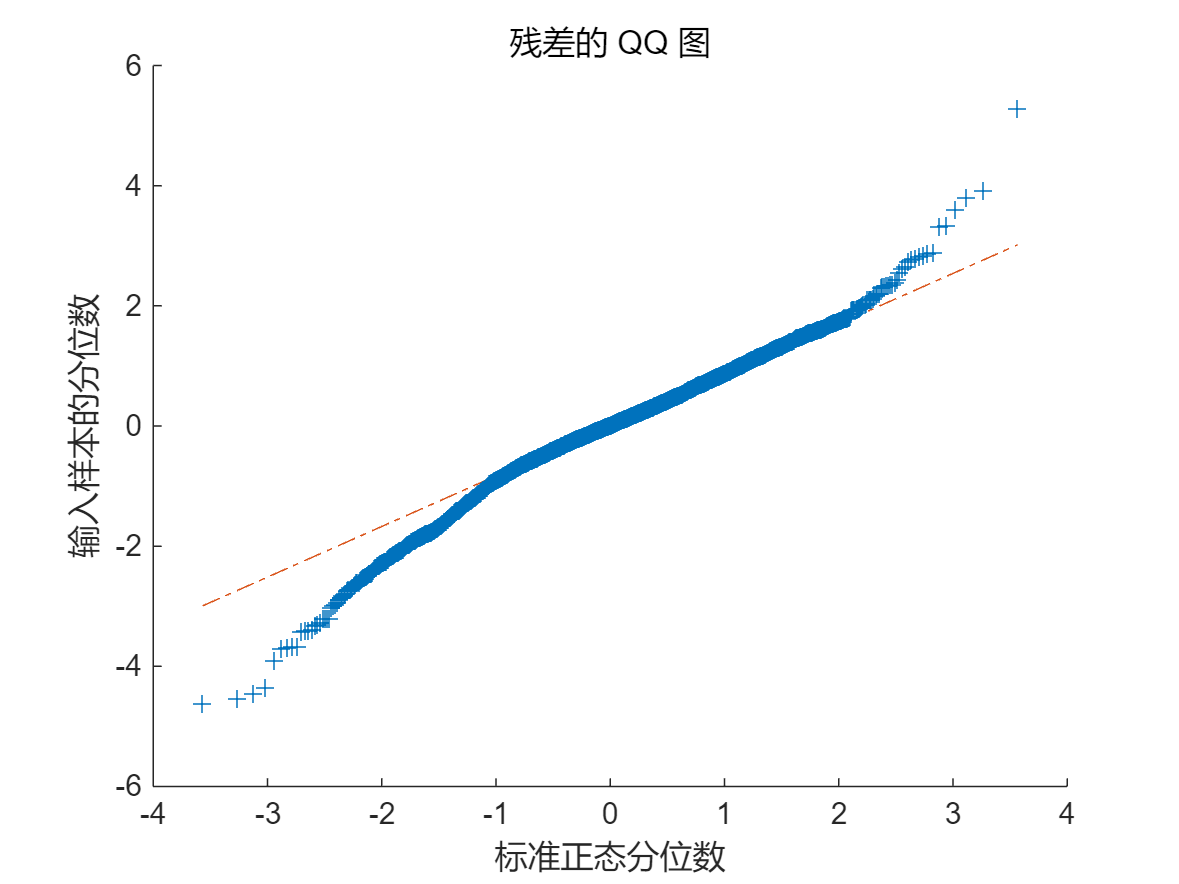


% 提取残差
[res_ar_garch, v_ar_garch] = infer(fit, port_returns);
std_res_ar_garch = res_ar_garch ./ sqrt(v_ar_garch);


% 计算残差的峰度
kurtosis_value = kurtosis(std_res_ar_garch);

qqplot(std_res_ar_garch);
title('残差的 QQ 图');


res_kurt = kurtosis(std_res_ar_garch)

res_kurt = 4.5181

res_skew = skewness(std_res_ar_garch)

res_skew = -0.4020


[h_lb_sq, p_lb_sq] = lbqtest(std_res_ar_garch.^2, 'Lags', 5, 'Alpha', 0.01)

h_lb_sq = logical
   0


p_lb_sq = 0.5657


if h_lb_sq==1
    disp('Remaining volatility clustering not fully captured by GARCH(1,1).');
else
    disp('No significant leftover volatility clustering.');
end

No significant leftover volatility clustering.


Q1.2 Using a rolling window of 6 months and starting on July 1st 2014, you have to estimate for each day the VaR at 90% and 99% confidence levels at one day horizon using at least four different methods

%Parameter settings for scrolling windows
%I use 120 here cause 126 will end up a negative start point in loop
windowSize = 120; %6 month
startDate = datenum('2014-07-01');
endDate = datenum('2024-12-31');
dates = datenum(date);

startIdx = find(dates >= startDate, 1);
endIdx = find(dates <= endDate, 1, 'last');
numDays = endIdx - startIdx + 1

numDays = 2643

%storage matrix
VaR_90 = zeros(numDays, 5); 
VaR_99 = zeros(numDays, 5);
eff_Returns = port_returns(startIdx:endIdx);

Q1.3 Given your VaR forecasts, compute the number of VaR violations for each model and each confidence level. 

use loop and 4 (or more) different methods to calculate:

**1. quantile** is a function used in MATLAB to compute quantiles (quantiles). Quantile is an important concept in statistics that is used to describe the location of a data distribution. For example, the 0.10 quantile (i.e., the 10th percentile) indicates that 10% of the values in the data are less than or equal to that quantile.

**-quantile(...) : Since VaR is a loss value, it usually takes a negative value.**

**2. Normal Distribution Method** is a Value at Risk (VaR) calculation method based on the assumption that returns follow a normal distribution. The core idea of this method is to use the properties of the normal distribution to calculate VaR at a specific confidence level by using the mean and standard deviation.

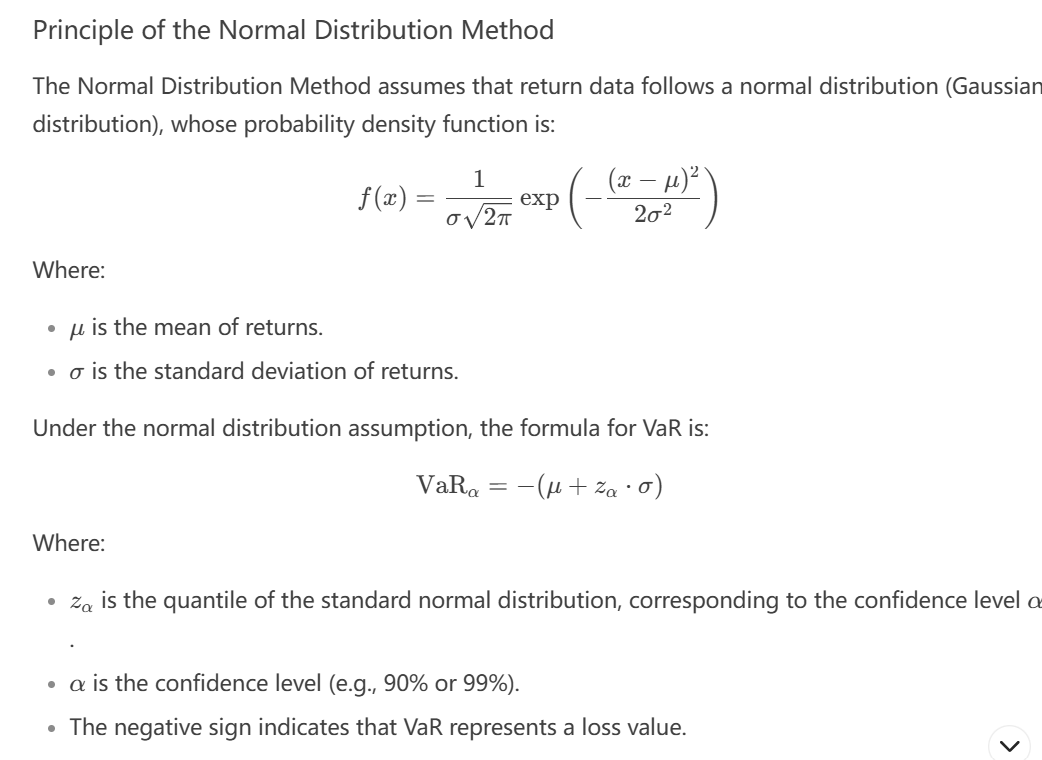

**3.The Cornish-Fisher method** is a technique used to adjust the quantiles of a normal distribution by incorporating higher moments (skewness and kurtosis) to more accurately estimate the risk of financial assets with non-normal distributions.

**Core Idea**

**Problem Context**: Traditional Value-at-Risk (VaR) calculations assume that returns follow a normal distribution. However, real-world data often exhibit skewness (asymmetry) and fat tails (excess kurtosis), leading to an underestimation of risk.

**Solution**: The Cornish-Fisher expansion adjusts the normal quantiles by introducing correction terms for skewness (S) and excess kurtosis (K), improving the accuracy of quantile estimates and, consequently, VaR calculations.

**Formula:**

**z_CF = z + (1/6)(z² -1)S + (1/24)(z³ -3z)K - (1/36)(2z³ -5z)S²**

Where:

z: The quantile of the standard normal distribution (e.g.,norminv(0.10).

*S*: Skewness of the returns (measures asymmetry in the distribution).

*K*: Excess kurtosis (kurtosis minus 3, measures the thickness of the tails).

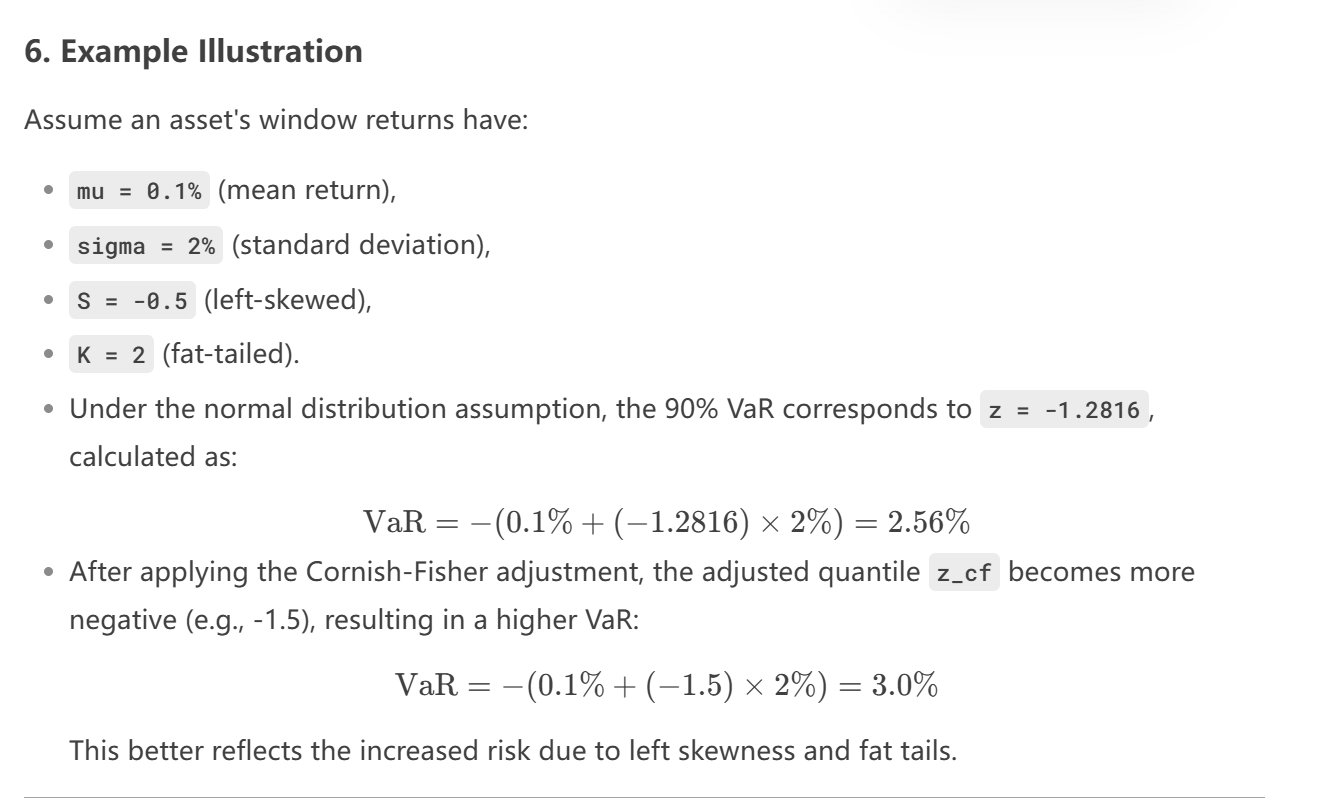

%For EWMA we need choose our lambda
%We can try to determine this in different ways before the main loop
lambdastar1 = fsolve(@(x) (1-x).*x^119-0.01,0.99)% prof formula


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


lambdastar1 = 0.9917

lambdastar2 = 0.94 %AI suggestion

lambdastar2 = 0.9400

%Comparing MSE
function mse = objectiveFunction(lambda, returns, windowSize)
    n = length(returns);
    predictions = zeros(n - windowSize, 1);
    for t = windowSize+1:n
        % EWMA calculation
        ewma = zeros(t-1, 1);
        ewma(1) = returns(1);
        for i = 2:t-1
            ewma(i) = lambda * ewma(i-1) + (1-lambda) * returns(i);
        end
        predictions(t-windowSize) = lambda * ewma(end) + (1-lambda) * returns(t);
    end
    % Calculate MSE
    mse = mean((returns(windowSize+1:end) - predictions).^2);
end

returns = port_returns; % Your return data
windowSize = 120; % Six-month window
lambdastar3 = fminbnd(@(x) objectiveFunction(x, returns, windowSize), 0.9, 0.99)

lambdastar3 = 0.9001

%I choose lambdastar3

%main loop 
for i = 1:numDays
    currentIdx = startIdx + i - 1;
    windowReturns = port_returns(currentIdx-windowSize:currentIdx-1);

    % method1：quantile
    VaR_90(i,1) = -quantile(windowReturns, 0.10);
    VaR_99(i,1) = -quantile(windowReturns, 0.01);

    % method2：Normal Distribution Method
    mu = mean(windowReturns);
    sigma = std(windowReturns);
    VaR_90(i,2) = -(mu + norminv(0.10)*sigma);
    VaR_99(i,2) = -(mu + norminv(0.01)*sigma);

     % method3：Cornish-Fisher
    S = skewness(windowReturns);
    K = kurtosis(windowReturns) - 3;
    z90 = norminv(0.10);
    z99 = norminv(0.01);
    z90_cf = z90 + (z90^2-1)*S/6 + (z90^3-3*z90)*K/24 - (2*z90^3-5*z90)*S^2/36;
    z99_cf = z99 + (z99^2-1)*S/6 + (z99^3-3*z99)*K/24 - (2*z99^3-5*z99)*S^2/36;
    VaR_90(i,3) = -(mu + z90_cf*sigma);
    VaR_99(i,3) = -(mu + z99_cf*sigma);

    % method4：EWMA
    lambda = 0.9001;
    sigma2 = zeros(size(windowReturns));
    sigma2(1) = windowReturns(1)^2;
    for t = 2:length(windowReturns)
        sigma2(t) = lambda*sigma2(t-1) + (1-lambda)*windowReturns(t-1)^2;
    end
    VaR_90(i,4) = -(mu + sqrt(sigma2(end))*norminv(0.10));
    VaR_99(i,4) = -(mu + sqrt(sigma2(end))*norminv(0.01));

    try
        % build modle
        arimaModel = arima('ARLags', 1:2, 'MALags', 1:2, 'Constant', 0);  % ARIMA(2,0,2)
        garchModel = garch('GARCHLags', 1, 'ARCHLags', 1);                % GARCH(1,1)
        arimaModel.Variance = garchModel;

        % Fitted model (assuming zero mean return)
        [estModel, ~, ~] = estimate(arimaModel, windowReturns, 'Display', 'off');

        % Predicting the conditional variance of the next period
        [~, sigma2_forecast] = forecast(estModel, 1, 'Y0', windowReturns);

        % Calculation of VaR
        VaR_90(i,5) = -sqrt(sigma2_forecast) * norminv(0.10);
        VaR_99(i,5) = -sqrt(sigma2_forecast) * norminv(0.01);
    catch
        % when model fit fails use
        sigma_backup = std(windowReturns);
        VaR_90(i,5) = -(sigma_backup * norminv(0.10));
        VaR_99(i,5) = -(sigma_backup * norminv(0.01));
    end
end
    

Kupiec Test (Unconditional Coverage Test)

1. **Purpose and Principle**

The Kupiec test (also known as the proportion test) is used to verify whether the **actual VaR violation rate** matches the confidence level claimed by the model. For example:

- For a 95% VaR, the expected violation rate is 5% (i.e., approximately 5 violations every 100 days).

- If the actual violation rate significantly deviates from the expected rate, the model may either underestimate or overestimate risk.

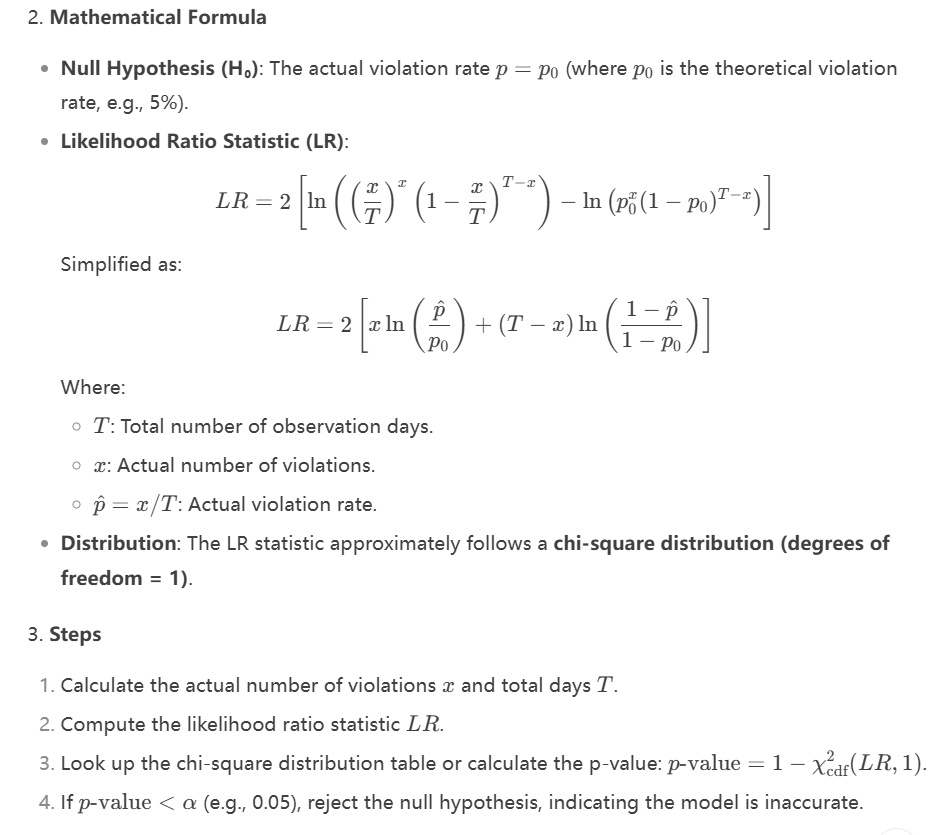

Christoffersen Test (Conditional Coverage Test)

1. **Purpose and Principle**

The Christoffersen test extends the Kupiec test by further examining the **independence of violation events**. Even if the violation rate matches expectations, if violations cluster over time (e.g., consecutive violations during a crisis), the model may still fail.

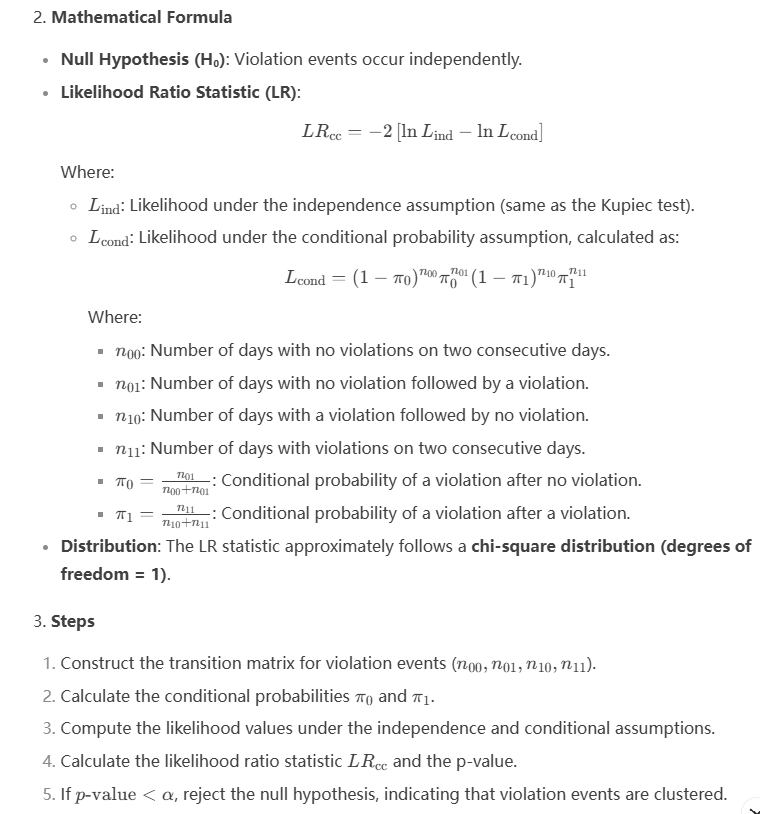

%% Step 3: Calculate the number of breakthroughs
violations_90 = eff_Returns < -VaR_90;
violations_99 = eff_Returns < -VaR_99;

sum_v90 = sum(violations_90);
sum_v99 = sum(violations_99);

%% Step 4: Backtesting Inspection
% Kupiec
function [LR, pval] = kupiec_test(violations, p)
    T = length(violations);
    x = sum(violations);
    phat = x/T;
    LR = 2*(x*log(phat/p) + (T-x)*log((1-phat)/(1-p)));
    pval = 1 - chi2cdf(LR,1);
end

% Conditional Coverage Test Functions
function [LRcc, pval] = christoffersen_test(violations, p)
    T = length(violations);
    n01 = sum(diff(violations) == 1);
    n10 = sum(diff(violations) == -1);
    n00 = sum(violations(1:end-1) == 0 & violations(2:end) == 0);
    n11 = sum(violations(1:end-1) == 1 & violations(2:end) == 1);
    
    pi0 = n01/(n00 + n01);
    pi1 = n11/(n10 + n11);
    LRI = (n00+n10)*log(1-p) + (n01+n11)*log(p);
    LRC = n00*log(1-pi0) + n01*log(pi0) + n10*log(1-pi1) + n11*log(pi1);
    LRcc = -2*(LRI - LRC);
    pval = 1 - chi2cdf(LRcc,1);
end

% test
methods = {'Historical simulation', 'Normal distribution','Cornish-Fisher','EWMA','ARIMA-GARCH'};
for m = 1:5
    % Kupiec检验
    [LR90, p90] = kupiec_test(violations_90(:,m), 0.10);
    [LR99, p99] = kupiec_test(violations_99(:,m), 0.01);
    
    % Conditional Coverage Test Functions
    [LRcc90, pcc90] = christoffersen_test(violations_90(:,m), 0.10);
    [LRcc99, pcc99] = christoffersen_test(violations_99(:,m), 0.01);
    
    fprintf('\nModel: %s\n', methods{m})
    fprintf('90%% VaR - number of VaR violations: %d, Kupiec p value: %.4f, CC p value: %.4f\n',...
        sum_v90(m), p90, pcc90)
    fprintf('99%% VaR - number of VaR violations: %d, Kupiec p value: %.4f, CC p value: %.4f\n',...
        sum_v99(m), p99, pcc99)


Model: Historical simulation


90% VaR - number of VaR violations: 272, Kupiec p value: 0.6191, CC p value: 0.0373


99% VaR - number of VaR violations: 36, Kupiec p value: 0.0762, CC p value: 0.0002



Model: Normal distribution


90% VaR - number of VaR violations: 259, Kupiec p value: 0.7303, CC p value: 0.0402


99% VaR - number of VaR violations: 79, Kupiec p value: 0.0000, CC p value: 0.0000



Model: Cornish-Fisher


90% VaR - number of VaR violations: 278, Kupiec p value: 0.3780, CC p value: 0.0738


99% VaR - number of VaR violations: 37, Kupiec p value: 0.0513, CC p value: 0.0002



Model: EWMA


90% VaR - number of VaR violations: 284, Kupiec p value: 0.2064, CC p value: 0.0947


99% VaR - number of VaR violations: 68, Kupiec p value: 0.0000, CC p value: 0.0000



Model: ARIMA-GARCH


90% VaR - number of VaR violations: 256, Kupiec p value: 0.5887, CC p value: 0.5729


99% VaR - number of VaR violations: 61, Kupiec p value: 0.0000, CC p value: 0.0000


end

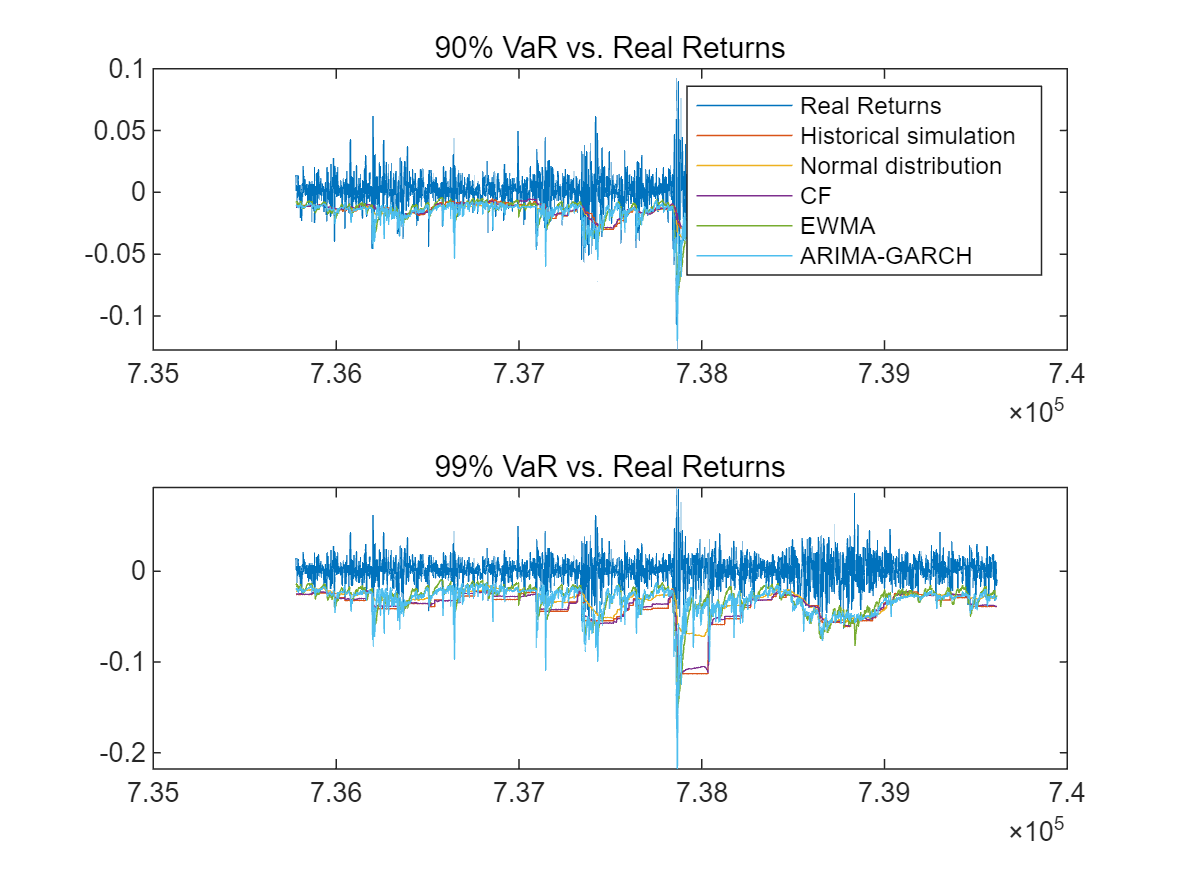

%% Step 5: Visualization of results
figure;
subplot(2,1,1)
plot(dates(startIdx:endIdx), eff_Returns)
hold on
plot(dates(startIdx:endIdx), -VaR_90)
title('90% VaR vs. Real Returns')
legend({'Real Returns','Historical simulation', 'Normal distribution','CF','EWMA','ARIMA-GARCH'})

subplot(2,1,2)
plot(dates(startIdx:endIdx), eff_Returns)
hold on
plot(dates(startIdx:endIdx), -VaR_99)

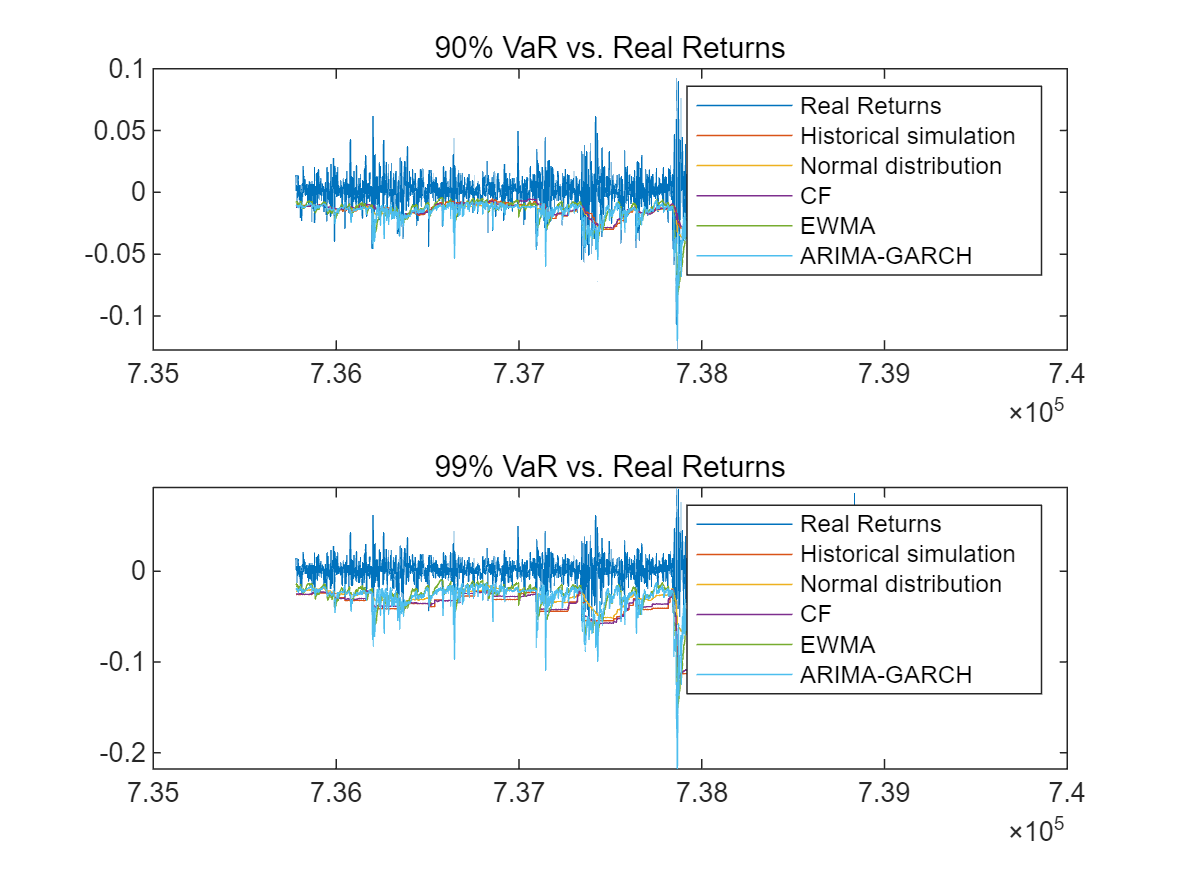

title('99% VaR vs. Real Returns')

legend({'Real Returns','Historical simulation', 'Normal distribution','CF','EWMA','ARIMA-GARCH'})